Analisis por municipio (selecciona municipio de 1-10)

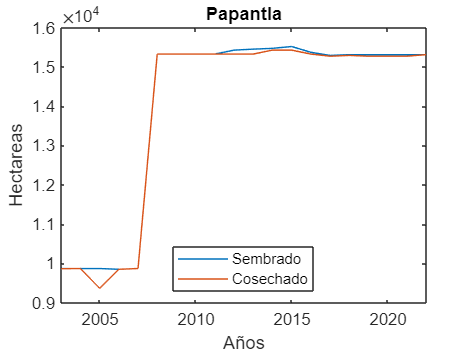

eage_x=2003:2022;
format long;
idx_municipio=4;
plot(eage_x,data_production(idx_municipio).Superficie_sembrada_Ha);
hold on;
plot(eage_x, data_production(idx_municipio).Superficie_cosechada_Ha);
title(data_production(idx_municipio).Municipio);
legend("Sembrado", "Cosechado","Location","south");
xlim([2003 2022])
ylabel("Hectareas")
xlabel("Años")
% ax = gca;
% ax.FontSize=18; 
hold off

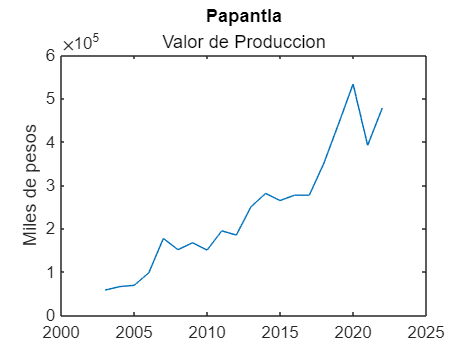


plot(eage_x, data_production(idx_municipio).Valor_Prod)
ylabel("Miles de pesos")
title(data_production(idx_municipio).Municipio,'Valor de Produccion');

## Redes neuronales

% parametros arreglo, area_studio, valor (1 naranja 0 no naranja)
% data_tab_function=f_aplica_formulas(arr_ndvi_sgf,study_area,1)

indxs=find(info_hdf.anio==2022);
% indxs=find(info_hdf.anio>=2003 & info_hdf.anio<=2022);

datos=arr_ndvi_sgf(:,:,indxs);
% data_tab_function=f_aplica_formulas(datos,study_area,1)
data_tab_test=f_aplica_formulas(datos,study_area,1)

data_tab_test = 27227×9 table
         Mediana             Promedio               Moda                 Rango              Desviacion             Minimos              Maximos                Mad            Valor
    _________________    _________________    _________________    _________________    __________________    _________________    _________________    __________________    _____

    0.576861904761905    0.600469565217391    0.438804761904762    0.381266666666667     0.091807287505087    0.438804761904762    0.820071428571429    0.0727092807633451      1  
    0.606333333333333    0.610131262939959    0.483795238095238    0.235033333333333    0.0690635375862339    0.48379523809

Cargar solo los datos requeridos

data_ndvi=data_tab_function(:,1:8);

## Implementacón de las redes neuronales 

% class_result=model_entrenado.predictFcn(data_ndvi);
% class_result=Model_trained.predictFcn(data_ndvi);
class_result=Trained_model.predictFcn(data_ndvi);

area_naranja=f_make_area(arr_ndvi_sgf,class_result,study_area);

area_clasificada=arr_ndvi_sgf;
area_clasificada(area_naranja==0)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,area_clasificada(:,:,1),archivo_kml,[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

## Hectareas encontradas

% 1 PX= 250m X 250m=62500 En hectareas 6.25Has
pix_area=sum(area_naranja,"all")

pix_area = 14907

disp("Hectareas Encontradas")   

Hectareas Encontradas



fprintf('%.2f\n', pix_area*6.25);

93168.75


## Hectareas por año

data_result=[];
indice=1;

areas_naranja=struct;

for eage=2003:2022
    indxs=find(info_hdf.anio==eage);
    
    datos=arr_ndvi_sgf(:,:,indxs);
    

      data_tab_function=f_aplica_formulas(datos,study_area,1);
%     data_tab_function=f_training_data(datos,study_area,1);


    
    data_ndvi=data_tab_function(:,1:8);
%     data_ndvi=data_tab_function(:,1);


% --------------------------------------------------TEMP
%     [~,~,pix_tam] =size(datos);
%     
%     d_res_tmp=[];
% 
%     for pxi_i=1:pix_tam
%         data_tab_function=f_training_data(datos(:,:,pxi_i),study_area,1);  
%         t_pxi=table2array(data_tab_function(:,1));
%         d_res_tmp=[d_res_tmp,t_pxi];
%     end
% --------------------------------------------------
    class_result=model_entrenado.predictFcn(data_ndvi);

    area_naranja=f_make_area(arr_ndvi_sgf,class_result,study_area);
    
    areas_naranja.Matriz(indice)={area_naranja(:,:)};
    
%     pix_area=sum(area_naranja,"all");
    pix_area=sum(class_result)
    
    data_result(indice)=pix_area*6.25;
%     data_result(indice)=pix_area;

   indice=indice+1;
end

pix_area = 7625

pix_area = 7382

pix_area = 6428

pix_area = 7762

pix_area = 4035

pix_area = 9535

pix_area = 6228

pix_area = 7803

pix_area = 6810

pix_area = 6000

pix_area = 8655

pix_area = 5916

pix_area = 2624

pix_area = 9081

pix_area = 8765

pix_area = 7406

pix_area = 9097

pix_area = 6466

pix_area = 7532

pix_area = 7338

## Data result

figure 
hold on;

eage_x=2003:2022;
format long;
idx_municipio=10;
plot(eage_x,data_production(idx_municipio).Superficie_sembrada_Ha);
% plot(eage_x, data_production(idx_municipio).Produccion_Ton, 'LineWidth', 2, 'LineStyle', ':','Color','m');

% 
% plot(eage_x, data_production(idx_municipio).Superficie_cosechada_Ha);
% title(data_production(idx_municipio).Municipio);
plot(eage_x, data_result, 'LineWidth', 2, 'LineStyle', '--','Color','r')
% legend("Sembrado", "Producción","Red Neuronal","Location","south");
% legend("Sembrado","Red Neuronal","Location","south");

title("Comparacion de resultados",data_production(idx_municipio).Municipio);

xlim([2003 2022])
ylabel("Hectareas")
xlabel("Años")
ax = gca;
ax.FontSize=20; 


[a02,a12,ajuste_2]=f_reglin(1:length(data_result),data_result)

a02 =      4.259220394736842e+04


a12 =      1.843139097744361e+02


ajuste_2 = 1.0e+04 *

   4.277651785714285   4.296083176691729   4.314514567669173   4.332945958646617   4.351377349624061   4.369808740601504   4.388240131578947   4.406671522556391   4.425102913533834   4.443534304511278   4.461965695488721   4.480397086466166   4.498828477443610   4.517259868421053   4.535691259398496   4.554122650375939   4.572554041353383   4.590985432330827   4.609416823308270   4.627848214285715


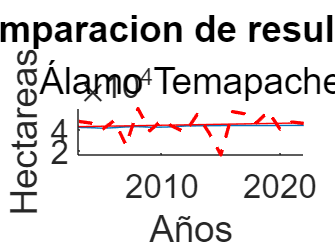


plot(eage_x, ajuste_2,"r")


hold off

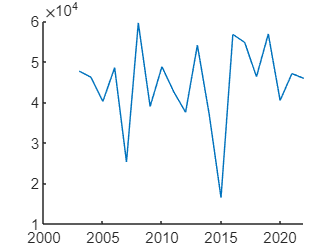


figure
hold on
plot(eage_x,data_result)
hold off

## Marcar zonas

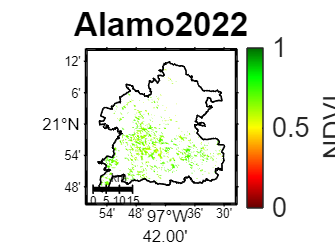

anio=2022;
indxs=find(info_hdf.anio==anio);
% indxs=find(info_hdf.anio>=2003 & info_hdf.anio<=2022);

datos=arr_ndvi_sgf(:,:,indxs);

data_tab_function=f_aplica_formulas(datos,study_area,1);
% data_tab_function=f_training_data(datos,study_area,1);

data_ndvi=data_tab_function(:,1:8);
% data_ndvi=data_tab_function(:,1);

class_result=model_entrenado.predictFcn(data_ndvi);

area_naranja=f_make_area(datos,class_result,study_area);

area_clasificada=datos;
area_clasificada(area_naranja==0)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,area_clasificada(:,:,1),archivo_kml+anio,[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

## Mostrar Todos los mapas 

anios_maps= areas_naranja;
[~,tam]=size(anios_maps.Matriz);

% for i=1:tam
%     figure;
%     
%     make_x=anios_maps.Matriz{1,i};
%     make_x(make_x==0)=NaN;
%     f_draw_map(lon_mapa,lat_mapa,lon,lat,make_x,archivo_kml+i,[0 1],"NDVI","NDVI");
%     f_draw_kml(dir_data,archivo_kml,1,'k');
%     ax = gca;
%     ax.FontSize=18; 
% end



## TEST MAPS

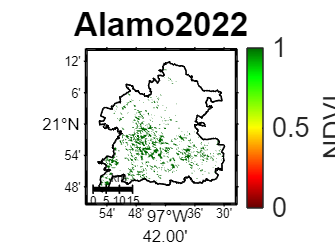

lat_map_x=lat;
lon_map_x=lon;
[h,w]=size(lat_map_x);

area_x=ones(h,w);

area_x(area_naranja==0)=NaN;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,area_x,archivo_kml+anio,[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

## Coordenadas A mostrar

% anio_test=diferencia;
anio_test=areas_naranja.Matriz{1,20};

lat_map_x=lat;
lon_map_x=lon;
[h,w]=size(lat_map_x);

% anio_test=areas_naranja.Matriz{1,18};

lat_map_x(anio_test==0)=0;
lon_map_x(anio_test==0)=0;

coordenadas_export=[];
idx_coor=1;
for i=1:h
    for j=1:w
        if (lat_map_x(i,j)~=0)
            coordenadas_export(idx_coor,1)=lat_map_x(i,j);
            coordenadas_export(idx_coor,2)=lon_map_x(i,j);
            idx_coor=idx_coor+1;
        end
    end
end



Relacion año mapa

% 1	2003
% 2	2004
% 3	2005
% 4	2006
% 5	2007
% 6	2008
% 7	2009
% 8	2010
% 9	2011
% 10	2012
% 11	2013
% 12	2014
% 13	2015
% 14	2016
% 15	2017
% 16	2018
% 17	2019
% 18	2020
% 19	2021
% 20	2022



## Diferencias entre mapas

anios_maps= areas_naranja;
map_1=17;
map_2=18;

mapa_1=anios_maps.Matriz{1,map_1};
mapa_2=anios_maps.Matriz{1,map_2};


arr_dif=mapa_1==mapa_2;
[h,w]=size(mapa_1);
diferencia=zeros(h,w);
diferencia(arr_dif==0)=1;
sum(mapa_1,"all")

ans =         9097


sum(mapa_2,"all")

ans =         6466


sum(diferencia,"all")

ans =         8107


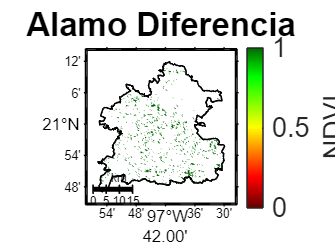


arr_temp=diferencia;
arr_temp(arr_dif==1)=NaN;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,arr_temp,archivo_kml+" Diferencia",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

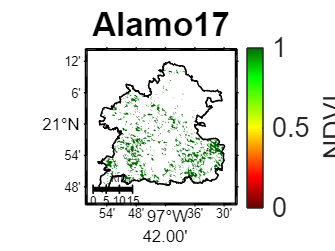



figure;
mapa_1(mapa_1==0)=NaN;
f_draw_map(lon_mapa,lat_mapa,lon,lat,mapa_1,archivo_kml+map_1,[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

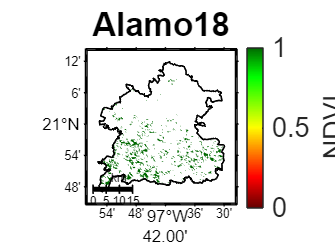



figure;
mapa_2(mapa_2==0)=NaN;
f_draw_map(lon_mapa,lat_mapa,lon,lat,mapa_2,archivo_kml+map_2,[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

% % Definir dos matrices A y B
% A = [1, 2; 3, 4];
% B = [1, 2; 3, 5];
% 
% % Realizar la operación de igualdad elemento a elemento
% resultado = A == B;
% 
% % Mostrar el resultado
% disp('Matriz A:');
% disp(A);
% 
% disp('Matriz B:');
% disp(B);
% 
% disp('Resultado de A == B:');
% disp(resultado);


% Perform k-means clustering using specified number of clusters (K value)
K = 3;
[clusterIndices,centroids] = kmeans(X,K);
clear K

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(X);
clusterMeans = grpstats(score,clusterIndices,"mean");
h = gscatter(score(:,1),score(:,2),clusterIndices,colormap("lines"));
for i2 = 1:numel(h)
    h(i2).DisplayName = strcat("Cluster",h(i2).DisplayName);
end
clear h i2 score
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h.DisplayName = "ClusterMeans";
clear h clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");